# s_oeBloodFluorophoreTongueSrch 

The notes are in s_oeBloodFluorophoreLipSrch.mlx.

From 500-600n, there is an excellent fit with the {'collagen1','KeratinPalero','FADLin'} fluorophores.  The deviation is mainly with the 450nm excitation light.  We think there was some light leaking through.  Joyce actually knows.  When we do the fits from 520-600 nm, even the 450 nm excitation light nails the data perfectly.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
[T,dataDir] = oeDatabaseCreate;

## Create fluorophore matrix and read database 

We create the base fluorophore emissions matrix.  It does not include blood (fluorophoresB).  Below, we sweep through different potential levels of blood optical density, checking how well the modified fluorophore matrix predicts the data samples.  Notice that the effective optical density of blood can depend on the wavelength of the excitation light.  Some lights will penetrate into the skin (substrate) more deeply than others, thus creating a longer path through the blood.

We tried many fluorophore files from the literature. These are described in in **s_oeFluorophoreEmissions.mlx**.  

Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  They exact emissions differ between labs, but the slopes are similar.

For the lip, there is no keratin, porphyrins, or chlorophyll.  We selected which to use in the s_oeBloodFluorophoreBasis.mlx script.

**Things we tried.**

- fluorophoreNames = {'collagen1','FAD_webfluor'}; -  Not enough dimensions. Fails to fit the data closely.

- fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor','NADH_webfluor'}; - Never chooses elastin

- fluorophoreNames = {'collagen1','FAD_webfluor','KeratinValdez'}; - Replaced NADH with Keratin.  Removed elastin. Too flat around 540, and a deep dive around 580.  General slope is OK.

- fluorophoreNames = {'collagen1','KeratinValdez','FADValdez'}; - Way off. Doesn't even get an OK fit of the blood.

- fluorophoreNames = {'CollagenWuQu','FADLin'}; - Way off, as above. Fails with blood

- fluorophoreNames = {'CollagenWuQu','FADValdez'}; - Way off as above.

- fluorophoreNames = {'CollagenWuQu','FAD_webfluor'}; - FIt is bad, but the blood is OK.

- fluorophoreNames = {'CollagenWuQu','elastin_webfluor','FADValdez'}; - Another blood miss.

- fluorophoreNames = {'collagen7','elastin_webfluor','FADValdez'}; - This collagen is goofy, and the fits are bad including the blood.

**Our winners so far**

- fluorophoreNames = {'CollagenWuQu','NADH_webfluor','FADLin'}; - Best fit so far.  

- fluorophoreNames = {'collagen1','NADH_webfluor','FADLin'}; - Still good if we swap collagen1 for ColalgenWuQu.  That's a good thing.  

- fluorophoreNames = {'collagen1','KeratinPalero','FADLin'}; -  This keratin is close to NADH

We should also try deoxygenated blood at some point, by adding in a collagen-deoxy column.

fluorophoreNamesB = {'collagen1','KeratinPalero','FADLin'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## 405/415 nm excitation

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
odError = zeros(numel(odLevels),numel(subjects));  
ods = zeros(numel(subjects),1);    
rmse = zeros(size(subjects));

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405,'e level',980);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415,'e level',910);
    tongueFiles = cat(1,files405,files415);

    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 19.00
OD across subjects for 405/415nm 18.00
OD across subjects for 405/415nm 18.00
OD across subjects for 405/415nm 20.00


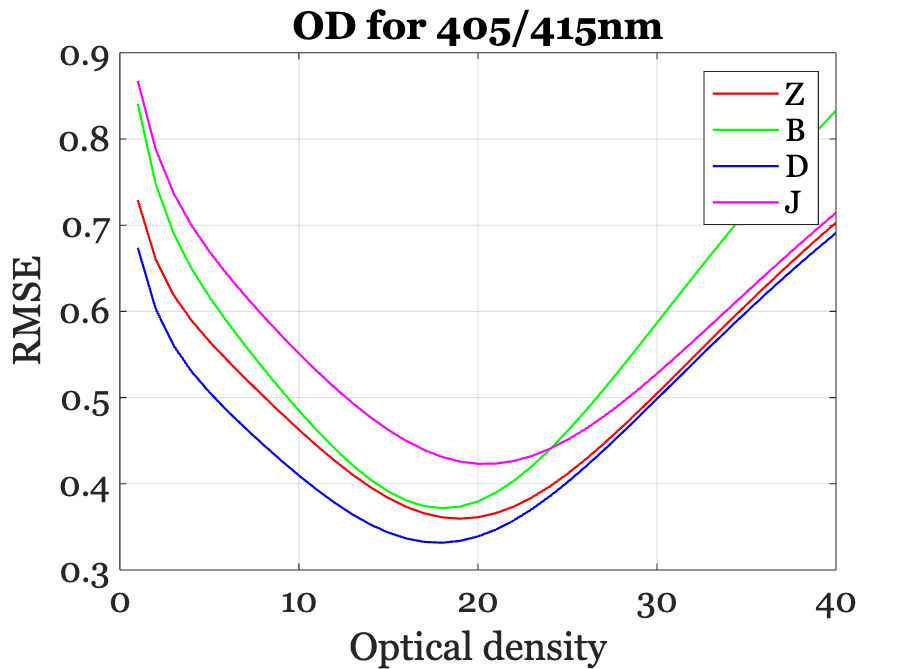


% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the proper optical density and plot

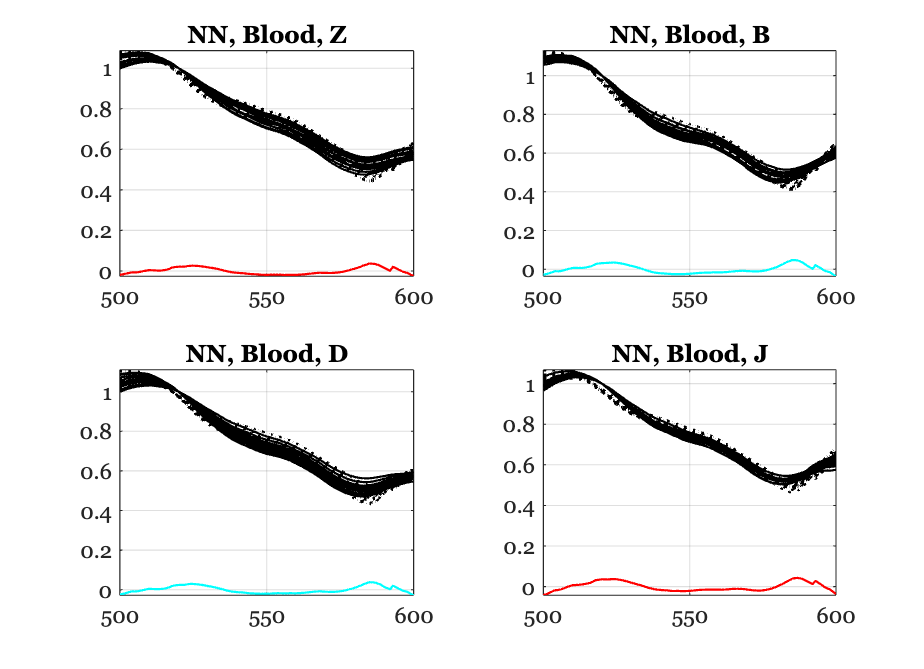

Subject Z
   12.1629   12.0093   11.3680   12.8962   11.2601   11.0671   11.0194   11.2303   10.9595   10.7347   11.6211   12.8557   10.4958   10.7308   10.6931
    0.8235    0.8072    0.7923    0.8342    0.6939    0.7369    0.7008    0.7696    0.7264    0.7368    0.7060    0.8366    0.7914    0.7814    0.7825
    0.4645    0.4785    0.4956    0.4474    0.5570    0.5275    0.5562    0.5045    0.5385    0.5312    0.5442    0.4394    0.4984    0.5012    0.5008

Subject B
   16.5127   13.4337   14.7397   18.5435   16.7955   17.3000   16.4968   17.9982   16.2936   17.0350   16.1715   15.4401   14.0921   15.2458
    0.8047    0.7750    0.7824    0.8193    0.8288    0.8441    0.8563    0.8161    0.8281    0.8395    0.8545    0.8130    0.8033    0.7971
    0.4350    0.4863    0.4676    0.3994    0.4113    0.3956    0.3959    0.4074    0.4162    0.4012    0.3999    0.4363    0.4586    0.4480

Subject D
   13.1737   13.2820   14.1168   11.4024   11.1003   11.4596   12.2424   10.9122   11.2365  

ieFigure;
tiledlayout(2,2);

deoxyblood = medium('deoxy_molarExtinctionCoefficient.mat','wave',wave);
deoxyblood.opticalDensity = 5;

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames]  = oeApplyBlood(fluorophoresB,fluorophoreNamesB,...
        oxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end
    residual = tongueData - fluorophores*wgtsNN;
    rmse(ii) = norm(residual(:),2);

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:', ...
        wave,mean(residual,2));
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

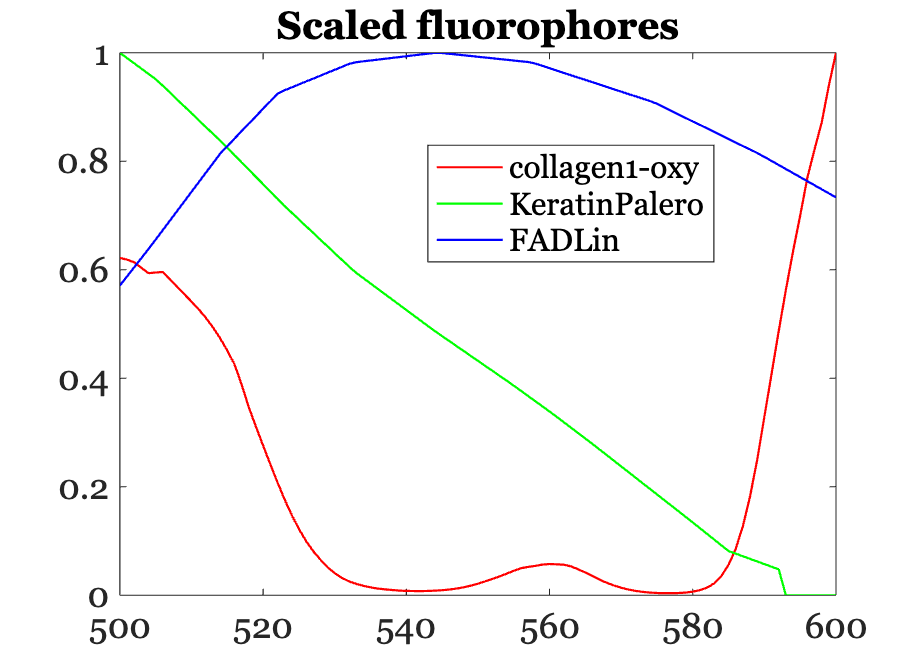


ieFigure; 
mx = max(fluorophores);
plot(wave,fluorophores*diag(1./mx));
title('Scaled fluorophores');
legend(fluorophoreNames);

legend(["collagen1-oxy", "KeratinPalero", "FADLin"], "Position", [0.4630 0.6080 0.3095, 0.1743])


disp(rmse); 

    0.6400    0.7987    0.6576    0.8558



## Create 450 nm blood optical density levels

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','tongue',...
        'e wave',450);
    tongueData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 23.00
OD across subjects for 405/415nm 23.00
OD across subjects for 405/415nm 22.00
OD across subjects for 405/415nm 25.00


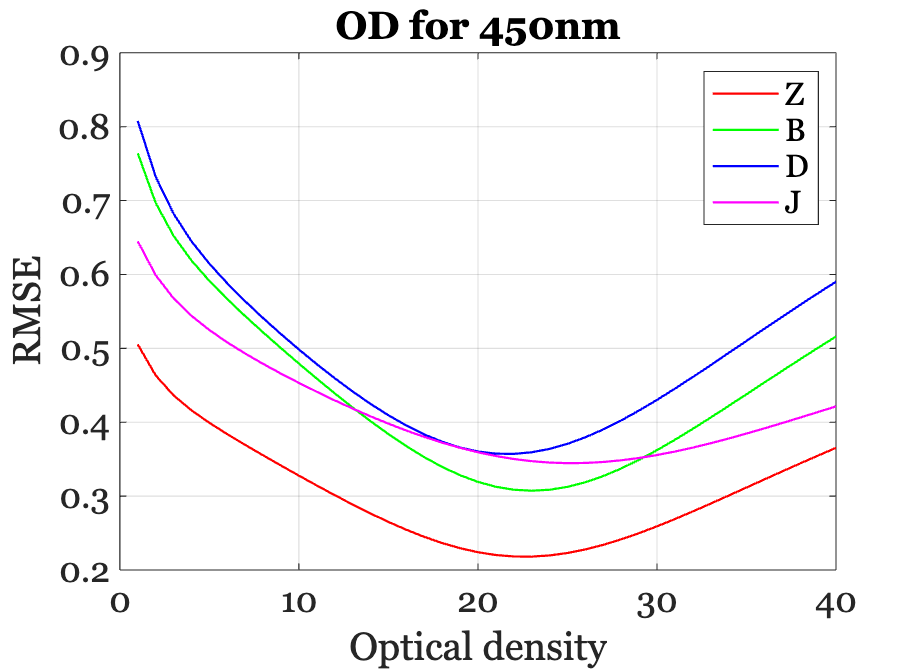



% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## 450 nm excitation light

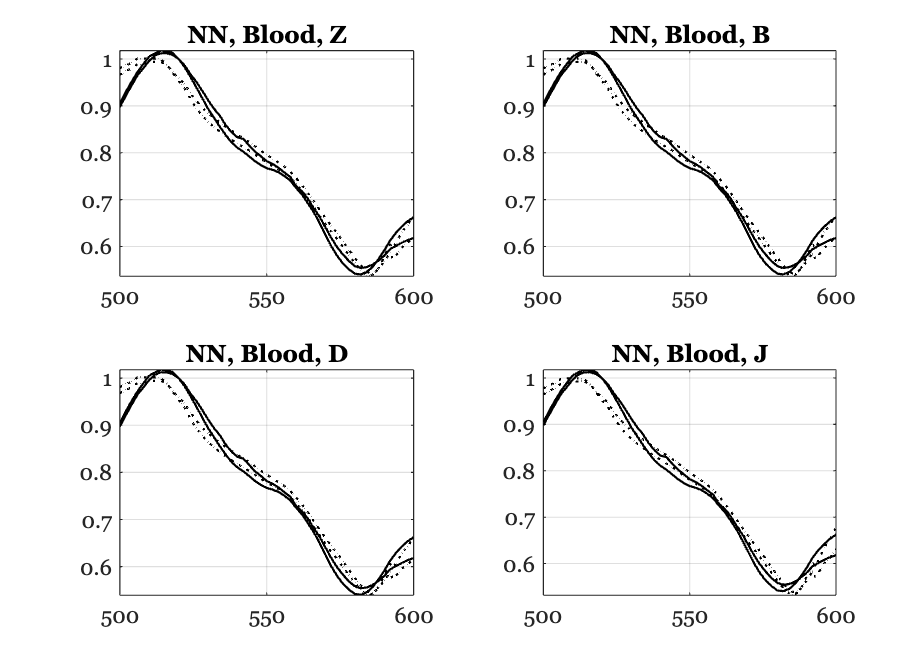

Subject Z
   12.4838    9.8501
    0.6124    0.6370
    0.5711    0.5811

Subject B
   12.4838    9.8501
    0.6124    0.6370
    0.5711    0.5811

Subject D
   11.9471    9.4232
    0.6011    0.6281
    0.5731    0.5827

Subject J
   13.5769   10.7199
    0.6343    0.6542
    0.5670    0.5778



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)
    wgtsNN = zeros(size(fluorophoresB,2),size(tongueData,2));

    oxyblood.opticalDensity = ods(ii);
    fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end